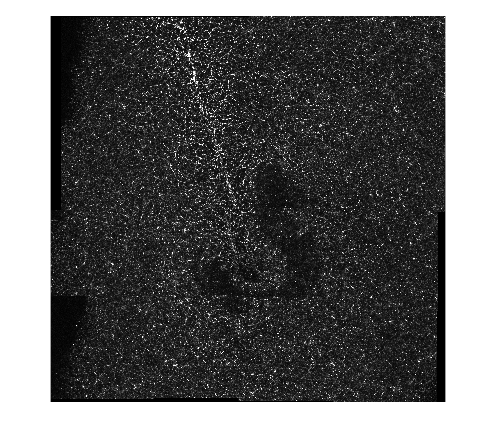

im_confocal_m=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C2-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_m,[]);

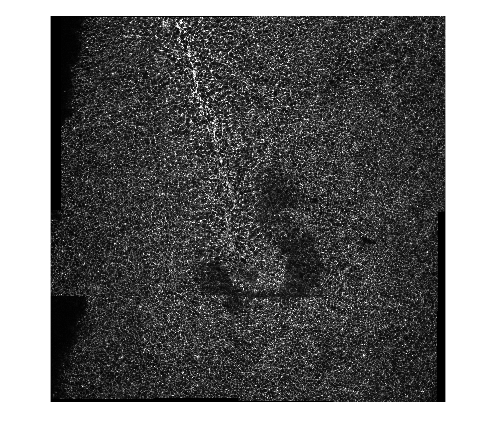

im_confocal_a=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C3-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_a,[]);

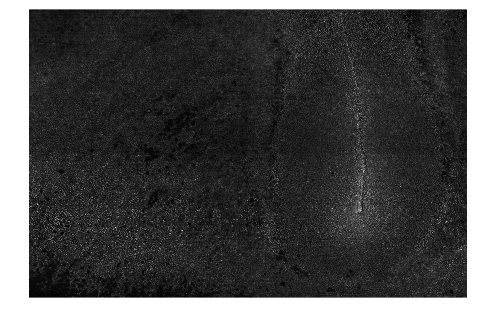

im_245=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\DSLM_expk\expk0245\0003_merge\merged_images\merge\img_0400.tif'));
imshow(im_245,[]);

DLSM_pixel=.65 ;%microns
confocal_pixel = 1/5.548 ;
confocal_tile = @(x) round(x*DLSM_pixel/confocal_pixel); %to get 
%equivalent tile size to 180, 256, etc pixel tiles on DLSM images

tile_size_DSLM=100;
tile_size_confocal=confocal_tile(tile_size_DSLM)

tile_size_confocal = 361

loc1_DSLM = [6200, 2000] %right of streak

loc1_DSLM =         6200        2000


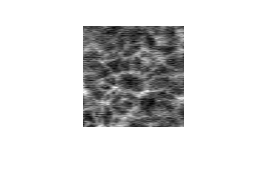

data=im_245(loc1_DSLM(2):loc1_DSLM(2)+tile_size_DSLM, loc1_DSLM(1):loc1_DSLM(1)+tile_size_DSLM);
imshow(data,[]);

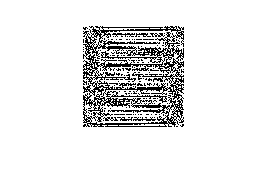

FT_loc1_DSLM = fft2(imadjust(data));
imshow(FT_loc1_DSLM,[0,10]);

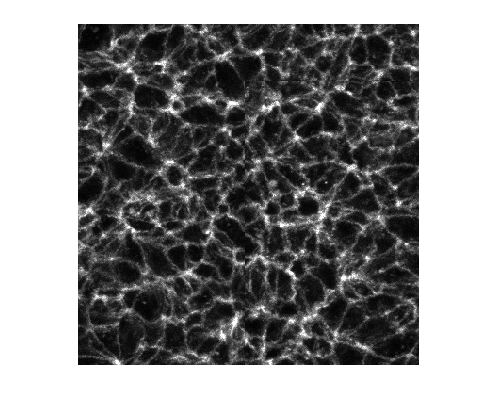

loc1 = [2700,850]; %in upper right uniform area
tile1a = im_confocal_a(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1a,[])

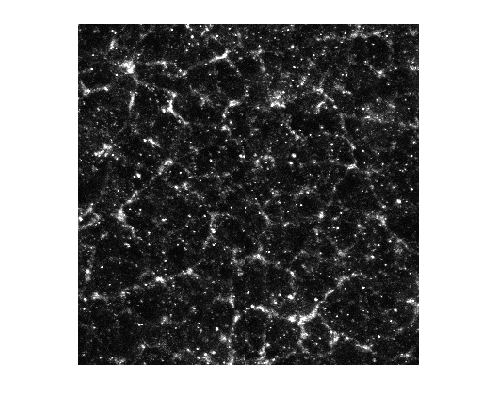

tile1m = im_confocal_m(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1m,[])

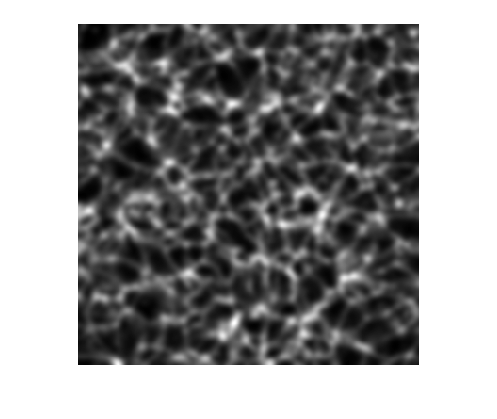

imshow(imgaussfilt(tile1a,3),[])